## *RTC*

fkine 		forward kinematics

A 			link transforms

trchain 		forward kinematics as a chain of elementary transforms

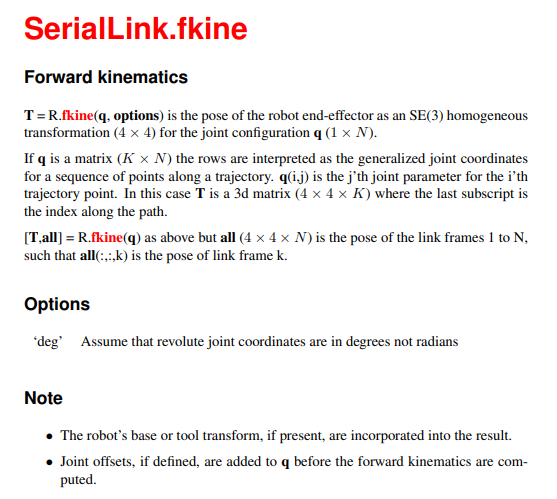

load('RVC')
T_RVC = R.fkine([q1 q2 q3 q4 q5 q6 q7])

T_RVC =     0.0000    0.0000    1.0000  341.3700
   -0.0000   -1.0000    0.0000    0.0000
    1.0000   -0.0000   -0.0000  598.1600
         0         0         0    1.0000


## *RST*

*Cinemática*

getTransform		Get transform between body frames

randomConfiguration	Generate random configuration of robot

homeConfiguration	Get home configuration of robot

show			Mostrar modelo robot en una figura

[`transform`](https://la.mathworks.com/help/robotics/ref/rigidbodytree.gettransform.html#bvan89q-1-transform) `= getTransform(`[`robot`](https://la.mathworks.com/help/robotics/ref/rigidbodytree.gettransform.html#bvan89q-1-robot)`,`[`configuration`](https://la.mathworks.com/help/robotics/ref/rigidbodytree.gettransform.html#bvan89q-1-configuration)`,`[`bodyname`](https://la.mathworks.com/help/robotics/ref/rigidbodytree.gettransform.html#bvan89q-1-bodyname)`)` computes the transform that converts points in the `bodyname` frame to the robot base frame, using the specified robot configuration.

load('RST')
configuration = homeConfiguration(robot);
%transform = getTransform(robot,configuration,'b7','b1')
transform = getTransform(robot,configuration,'b7')

transform =     0.0000    0.0000    1.0000  341.3700
   -0.0000   -1.0000    0.0000    0.0000
    1.0000   -0.0000   -0.0000  598.1600
         0         0         0    1.0000
